**BUYING ON MARGIN**  

�  Investors can buy securities either with cash or with part cash and part borrowing.

�  Buying securities on margin means that the investors borrows part of the purchase price from the broker.

�  Margin is the amount contributed by the investor.

�  The securities serve as **collateral** for the loan.

�  In this way, the investor creates financial leverage.

**INITIAL MARGIN REQUIREMENT**  

�  The minimum amount of margin that must be in the account when

the purchase is made is called the **initial margin requirement**.

�  Consider a 50% initial margin requirement.

�  In the previous example your $10,000 met the initial margin

requirement for buying 1000 shares at $20 a share.

Margin transactions can have important impact on the investment.

Look at an **example** here.

clear
x=1 % initial money

x = 1

r=10/100 % margin interest, annual

r = 0.1000

g=30/100 % expected stock gain, annual

g = 0.3000

y=2 % # of years borrowing

y = 2



% exptected profit in percentage

for g=[-30,30]/100
    if g>0
        out.case='grow';
    else
        out.case='shink';
    end
    out.g=g;
    % case 1: no margin
    out.p1=(x*(1+g)^y-x)/x;
    % case 2: no margin
    out.p2=(2*x*(1+g)^y-x*(1+r)^y-x)/x;
    out
end

out = struct with fields:
    case: 'shink'
       g: -0.3000
      p1: -0.5100
      p2: -1.2300


out = struct with fields:
    case: 'grow'
       g: 0.3000
      p1: 0.6900
      p2: 1.1700


## Possible loss and gain if there's no margin call

Try to find out the possible loss and gain if g is close to 1 or -1

clear
x=1 % initial money

x = 1

r=10/100 % margin interest, annual

r = 0.1000

g=30/100 % expected stock gain, annual

g = 0.3000

y=2 % # of years borrowing

y = 2



% exptected profit in percentage

for g=[-99,99]/100
    if g>0
        out.case='grow';
    else
        out.case='shink';
    end
    out.g=g;
    % case 1: no margin
    out.p1=(x*(1+g)^y-x)/x;
    % case 2: no margin
    out.p2=(2*x*(1+g)^y-x*(1+r)^y-x)/x;
    out
end

out = struct with fields:
    case: 'shink'
       g: -0.9900
      p1: -0.9999
      p2: -2.2098


out = struct with fields:
    case: 'grow'
       g: 0.9900
      p1: 2.9601
      p2: 5.7102




fun_noMargin=@(g,y) (1+g).^y-1;
fun_withMargin=@(g,y) 2*(1+g).^y-(1+r).^y-1;


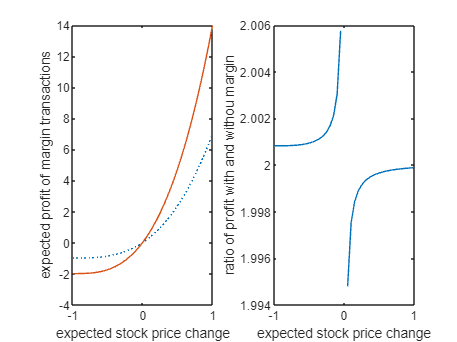


% Given y, look at the effect of g,

g_vec=linspace(-1,1,41);
figure
for y = [3]

    p_no_margin=fun_noMargin(g_vec,y);

    p_with_margin=fun_withMargin(g_vec,y);
    subplot(1,2,1)
    plot(g_vec, p_no_margin,':',g_vec,p_with_margin,'-')
    xlabel('expected stock price change')
    ylabel('expected profit of margin transactions')
    subplot(1,2,2)
    plot(g_vec, p_with_margin./p_no_margin,'-')

    xlabel('expected stock price change')
    ylabel('ratio of profit with and without margin')
end


% Given g, look at the effect of y
r=0.1/365

r = 2.7397e-04

g=0.18/365 % convert the rates to daily

g = 4.9315e-04

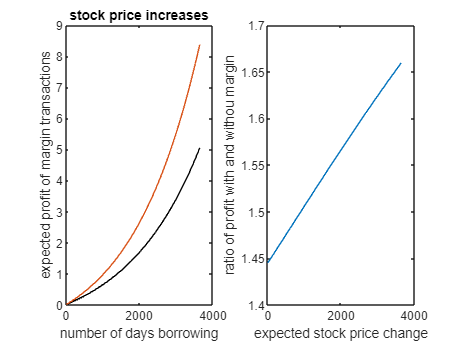

y_vec=(1:365)*10;


fun_noMargin=@(g,y) (1+g).^y-1;
fun_withMargin=@(g,y) 2*(1+g).^y-(1+r).^y-1;

figure

p_no_margin=fun_noMargin(g,y_vec);

p_with_margin=fun_withMargin(g,y_vec);
subplot(1,2,1)
plot(y_vec, p_no_margin,'k',y_vec,p_with_margin,'-')
xlabel('number of days borrowing')
ylabel('expected profit of margin transactions')
title('stock price increases')

subplot(1,2,2)
plot(y_vec, p_with_margin./p_no_margin,'-')

xlabel('expected stock price change')
ylabel('ratio of profit with and without margin')

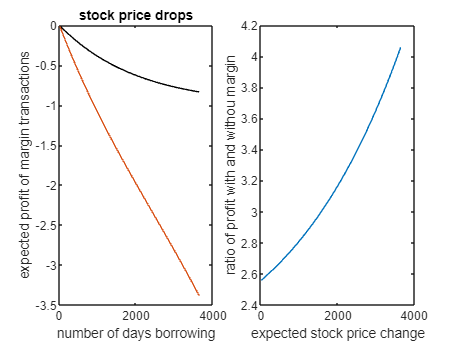




g=-g;
figure

p_no_margin=fun_noMargin(g,y_vec);

p_with_margin=fun_withMargin(g,y_vec);
subplot(1,2,1)
plot(y_vec, p_no_margin,'k',y_vec,p_with_margin,'-')
xlabel('number of days borrowing')
ylabel('expected profit of margin transactions')
title('stock price drops')
subplot(1,2,2)
plot(y_vec, p_with_margin./p_no_margin,'-')
xlabel('expected stock price change')
ylabel('ratio of profit with and without margin')

**MAINTENANCE MARGIN**  

�  The minimum amount the margin can decline to without an investor having to take any action is called the maintenance margin.

�  If your margin in the account drops below this threshold level, you will receive a margin call – essentially to add more cash

Suppose that the maintenance margin requirement is 30%, and instead of going up if Fast Cars share price drops down by 30%.  

Or, debt percentage should be below 70%.

The debt is matched to be 1 unit if 1 unit is posted as margin by the investor.

clear
(2*(1-0.3)-1)/(2*(1-0.3))

ans = 0.2857

4/14

ans = 0.2857

When will a margin call be triggered?

Margin call is a request sent to the investor when the margin (or, the assest as a collateral) falls below a threshold.

down=linspace(0,0.5,20)'

down =          0
    0.0263
    0.0526
    0.0789
    0.1053
    0.1316
    0.1579
    0.1842
    0.2105
    0.2368



margin_percent=(2*(1-down)-1)./(2*(1-down))

margin_percent =     0.5000
    0.4865
    0.4722
    0.4571
    0.4412
    0.4242
    0.4062
    0.3871
    0.3667
    0.3448


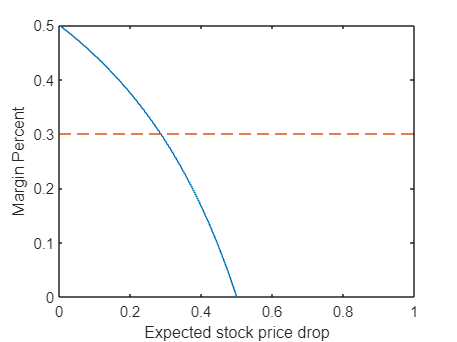

figure
plot(down, margin_percent)
hold on
plot([0, 1],[0.3,0.3],'--')
hold off

xlabel('Expected stock price drop')
ylabel('Margin Percent')

With a margin call threshold set to 30%, what is the maximum money that the invest may lose? 

Suppose the invester start with 1 unit of cash/asset as margin, and they borrows 1 unit from the broker, and then the invester can buy the stock with 2 units of money.

If the stock price drops, there's a threshold 30% to trigger the margin call. If the investor decided to not invest more money, how much they will lose?

clear
syms down call
eq=(2*(1-down)-1)/(2*(1-down))-call

$$eq = \frac{2\,\mathrm{down}-1}{2\,\mathrm{down}-2}-\mathrm{call}$$

solve(eq)

$$ans = \frac{\mathrm{call}}{2\,\left(\mathrm{call}-1\right)}+\frac{1}{2}$$

eval(ans)

$$ans = \frac{\mathrm{call}}{2\,\mathrm{call}-2}+\frac{1}{2}$$



eq2=1/(2*(1-down))-(1-call)

$$eq2 = \mathrm{call}-\frac{1}{2\,\mathrm{down}-2}-1$$

the_down=solve(eq2)

$$the\_down = \frac{1}{2\,\left(\mathrm{call}-1\right)}+1$$

eval(ans)

$$ans = \frac{\mathrm{call}}{2\,\mathrm{call}-2}+\frac{1}{2}$$


fun_call=matlabFunction(the_down)

fun_call = function_handle with value:
    @(call)1.0./(call.*2.0-2.0)+1.0



call_vec=linspace(0,0.5,10)

call_vec =          0    0.0556    0.1111    0.1667    0.2222    0.2778    0.3333    0.3889    0.4444    0.5000


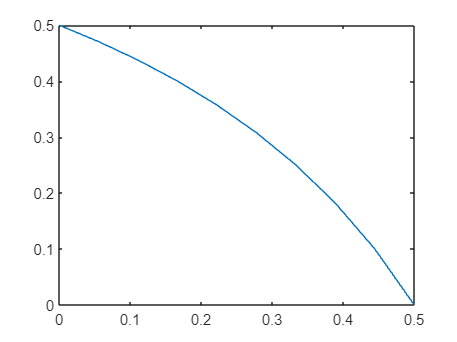

plot(call_vec,fun_call(call_vec))


% when threshold is 30%, without new investment, the margin transaction
% will stop when the stock price is down by:
stop_by=fun_call(0.3)

stop_by = 0.2857

% Now the total worth minus the borrowed money (before consider interest)
% is:
left=2*(1-stop_by)-1

left = 0.4286

% the loss will be
1-left

ans = 0.5714


% with a higher stop threshold, the percent drop will be smaller, and the
% total loss will be smaller.

